% double integrator plant
A = [0 1; 0 0];
B = [0; 1];
C = [2 0];
D = 0;

% Augmented dynamics:
F = [0 1; -1 0];
H = [0;1];
Aaug = [A zeros(2,2); H*C F];
Baug = [B;zeros(2,1)];

psf = [-3 -4 -5 -6];
K = place(Aaug,Baug,psf);
%% (c)
% This function makes the A,B,C,H,F matrices of the disk drive
% problem. 


% psf =  ;
t = linspace(0,10,200);
r = sin(t) + 2*cos(t);

% Open Loop Bode Plot
omega = logspace(-1,1);
[mag,phase] = bode(A,B,C,D,1,omega);

figure(1)
clf
 
subplot(2,1,1)

loglog(omega,mag)
ylabel('magnitude')
title('Bode plots of Disk Drive System')
subplot(2,1,2)
semilogx(omega,phase)
xlabel('frequency, rad/sec')
ylabel('phase, degrees')
set(findall(gcf,'type','line'),'linewidth',2)


Acl = Aaug - Baug*K

Acl =          0    1.0000         0         0
 -118.0000  -18.0000 -121.0000 -162.0000
         0         0         0    1.0000
    2.0000         0   -1.0000         0


Bcl = [0;0; -H]

Bcl =      0
     0
     0
    -1


Ccl = [C 0 0]

Ccl =      2     0     0     0


Dcl = 0

Dcl = 0

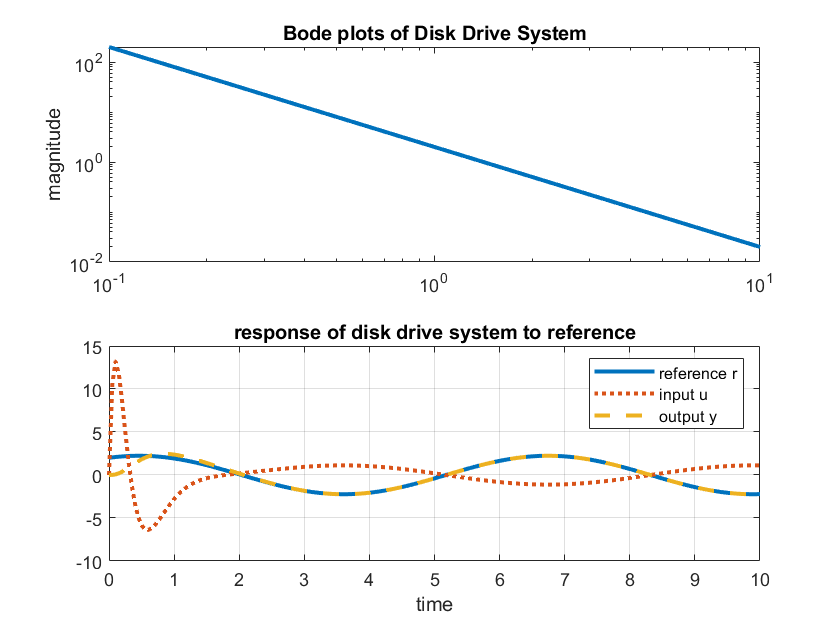



% simulate
Tyr = ss(Acl,Bcl,Ccl,0);
Tur = ss(Acl,Bcl,-K,0);
[y,x] = lsim(Tyr,r,t);
[u,x] = lsim(Tur,r,t);   % to get u substitute -K for Ccl.


% 
% y = step(Tyr,t);
% u = step(Tur,t);

plot(t,r,'-',t,u,':',t,y,'--')
grid
legend('reference r','input u','output y')
xlabel('time')
title('response of disk drive system to reference')
set(findall(gcf,'type','line'),'linewidth',2)

QUESTION e 

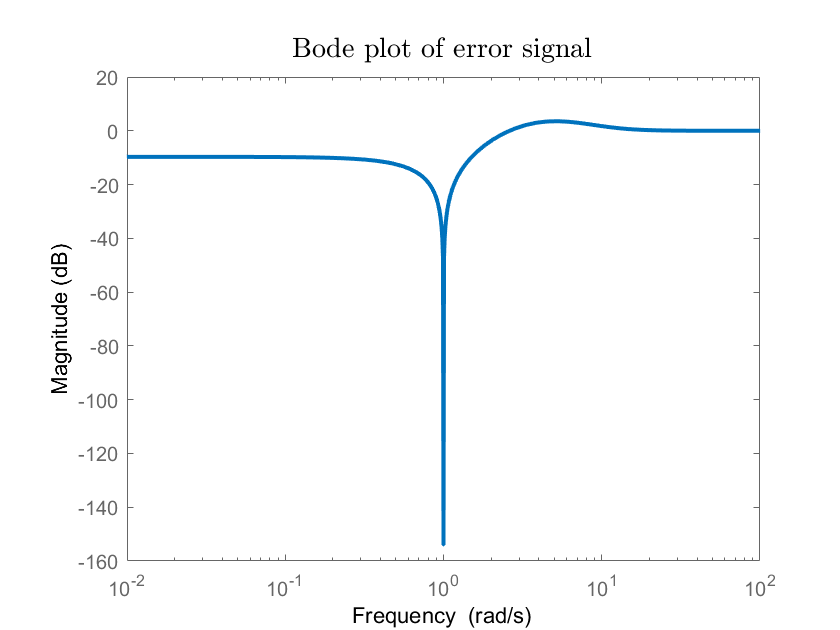

Tye = ss(Acl,Bcl,[2 0 0 0],-1);
% e = step(Tyr,t);
figure(3)
clf
 
bodemag(Tye)
h = title('Bode plot of error signal');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)